# This script focuses on the pid tuning of the Rhino 300 rpm motor(RMCS-5033)

% Initialising the variable for the continuous transfer function of the
% motor

R = 1.6;      % Armature Resistance(Ohm)
L = 0.001;    % Inductance(Henry)
K = 0.00636;  % Motor constant( V/rad)
b = 2.7e-6;   % Viscous friction of the motor at no load)
J_wheel = 0.1562;  % kgm^2 
J_rotor = 1e-6;   % negligible rotor inertia
N = 52.1;          % gear ratio(as present in the documentation of the motor)

J_reflected = J_wheel/(N^2);

J = J_rotor + J_reflected; % total inertia on the motor(using macannum wheel)



## Creating the transfer function s


% creating the transfer fucntion 
s = tf('s');
% Standard DC motor transfer function derived using physics and electronics
num = K;
den = [ (J*L)   (J*R + b*L)   (b*R + K^2) ];

G = tf(num, den);
motor_poles = pole(G)

motor_poles = 1.0e+03 *

   -1.5996
   -0.0005


## Display the open loop transfer function

disp('Open loop transfer function of the motor');

Open loop transfer function of the motor


G


G =
 
                  0.00636
  ---------------------------------------
  5.854e-08 s^2 + 9.367e-05 s + 4.477e-05
 
Continuous-time transfer function.


## Analyse the physical response for 12 V input

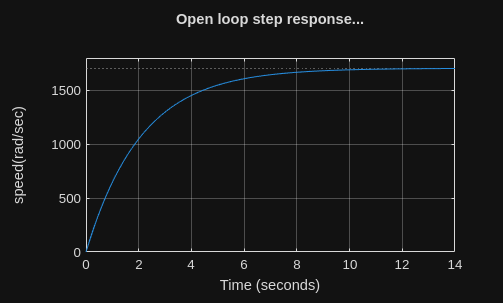

figure;
step(12 * G);
title('Open loop step response...');
ylabel('speed(rad/sec)');
grid on;

## Lienar  system analyser

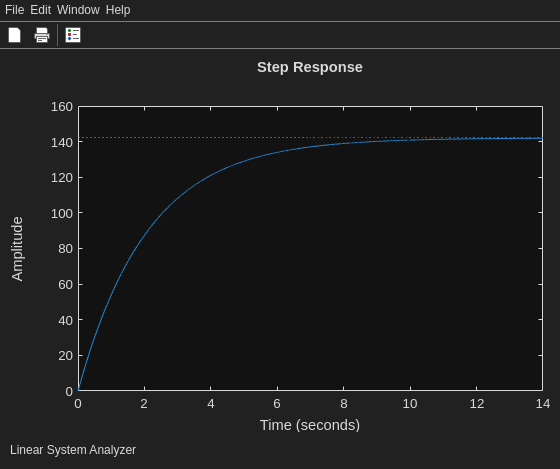

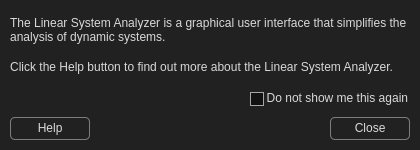

linearSystemAnalyzer('step', G, 0:0.001:14);

## First order transfer function

% creating the first order transfer function
% First we need to find the dc gain of the system
dcGain = dcgain(G);

% as the dominant pole is the -0.5, so 
time_const = 1/0.5

time_const = 2


% first order transfer fucntion
P_motor = dcGain/(time_const*s + 1);


## Starting the PID


% 1. Ask MATLAB to automatically calculate the optimal PI gains
[C_tuned, info] = pidtune(P_motor, 'PI');

% 2. Print those perfect gains to the screen so you have them!
disp('=== OPTIMAL TUNING RESULTS ===');

=== OPTIMAL TUNING RESULTS ===


disp(['Kp (Proportional): ', num2str(C_tuned.Kp)]);

Kp (Proportional): 0.0073377


disp(['Ki (Integral): ', num2str(C_tuned.Ki)]);

Ki (Integral): 0.011011


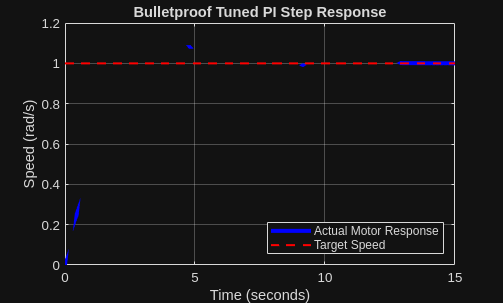


% 3. Building the closed-loop system using the newly tuned controller
sys_cl_tuned = feedback(C_tuned * P_motor, 1);

% 4. Generate the step response math manually (0 to 15 seconds)
[y, t] = step(sys_cl_tuned, 15); 

% 5. Build a bulletproof plot
figure;
set(gcf, 'Renderer', 'painters'); % Force software rendering
plot(t, y, 'b-', 'LineWidth', 3); % Force a massive line width (3px)
grid on;
title('Bulletproof Tuned PI Step Response');
xlabel('Time (seconds)');
ylabel('Speed (rad/s)');

% Plot the target reference line (1.0) in red
hold on;
plot([0 15], [1 1], 'r--', 'LineWidth', 1.5);
legend('Actual Motor Response', 'Target Speed', 'Location', 'Southeast');

## FIltered PID tuning

% 1. Ask MATLAB to automatically calculate optimal PIDF gains
% We use 'PIDF' (PID with Filter) to protect the physical hardware from encoder noise
[C_tuned, info] = pidtune(P_motor, 'PIDF');

% 2. Print those perfect gains to the screen so you have them!
disp('=== OPTIMAL TUNING RESULTS ===');

=== OPTIMAL TUNING RESULTS ===


disp(['Kp (Proportional): ', num2str(C_tuned.Kp)]);

Kp (Proportional): 0.0094156


disp(['Ki (Integral): ', num2str(C_tuned.Ki)]);

Ki (Integral): 0.0094099


disp(['Kd (Derivative): ', num2str(C_tuned.Kd)]);

Kd (Derivative): -0.00068388


disp(['Tf (Filter Time Constant): ', num2str(C_tuned.Tf)]);

Tf (Filter Time Constant): 0.52897


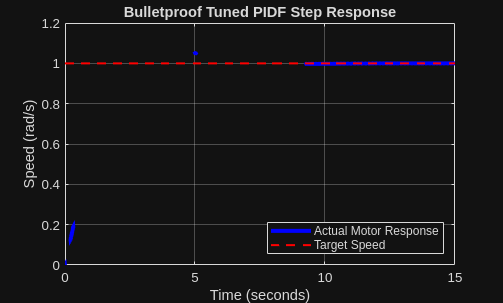


% 3. Building the closed-loop system using the newly tuned controller
sys_cl_tuned = feedback(C_tuned * P_motor, 1);

% 4. Generate the step response math manually (0 to 15 seconds)
[y, t] = step(sys_cl_tuned, 15); 

% 5. Build a bulletproof plot
figure;
set(gcf, 'Renderer', 'painters'); % Force software rendering
plot(t, y, 'b-', 'LineWidth', 3); % Force a massive line width (3px)
grid on;
title('Bulletproof Tuned PIDF Step Response');
xlabel('Time (seconds)');
ylabel('Speed (rad/s)');

% Plot the target reference line (1.0) in red
hold on;
plot([0 15], [1 1], 'r--', 'LineWidth', 1.5);
legend('Actual Motor Response', 'Target Speed', 'Location', 'Southeast');

## Discrete transfer function change

% Converting the continuous transfer function to a discrete transfer function
dis = c2d(G, 0.001, 'zoh');
disp('Discrete transfer function of the motor:');

Discrete transfer function of the motor:


disp(dis);

  tf with properties:

       Numerator: {[0 0.0340 0.0202]}
     Denominator: {[1 -1.2015 0.2019]}
        Variable: 'z'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 1.0000e-03
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



dis


dis =
 
   0.03403 z + 0.02016
  ----------------------
  z^2 - 1.202 z + 0.2019
 
Sample time: 0.001 seconds
Discrete-time transfer function.
